# I.  Continuous Wavelet Transform 

## 1.2. Wavelet properties

clearvars; close all; clc;

fs = 250;           % Sample frequency
N = 3000;           % Data length
t = (-N:N)/fs;      % Time scale
s = 0.01:0.1:2;     % Values of scaling factor

% Plotting the Mexican Hat wavelets with corresponding scales.

figure;

for i = 1:length(s)
    wavelet_s = mexican_hat_wavelet(t,s(i));
    subplot(10, 2, i);
    plot(t,wavelet_s);
    title(['s = ',num2str(s(i))])
    disp(['Mean of s = ',num2str(s(i)),' is ',num2str(mean(wavelet_s))]);
    disp(['Energy of s = ',num2str(s(i)),' is ',num2str(trapz(t,wavelet_s.^2))]);
    
end

Mean of s = 0.01 is -6.5837e-19


Energy of s = 0.01 is 1


Mean of s = 0.11 is 7.4817e-19


Energy of s = 0.11 is 1


Mean of s = 0.21 is -1.1868e-18


Energy of s = 0.21 is 1


Mean of s = 0.31 is 5.9901e-18


Energy of s = 0.31 is 1


Mean of s = 0.41 is -2.7943e-18


Energy of s = 0.41 is 1


Mean of s = 0.51 is 7.0989e-18


Energy of s = 0.51 is 1


Mean of s = 0.61 is 7.6729e-18


Energy of s = 0.61 is 1


Mean of s = 0.71 is -1.3054e-17


Energy of s = 0.71 is 1


Mean of s = 0.81 is 5.8726e-18


Energy of s = 0.81 is 1


Mean of s = 0.91 is -7.352e-19


Energy of s = 0.91 is 1


Mean of s = 1.01 is 1.7049e-17


Energy of s = 1.01 is 1


Mean of s = 1.11 is 1.287e-17


Energy of s = 1.11 is 1


Mean of s = 1.21 is 5.091e-18


Energy of s = 1.21 is 1


Mean of s = 1.31 is -5.3379e-18


Energy of s = 1.31 is 1


Mean of s = 1.41 is 1.2045e-16


Energy of s = 1.41 is 1


Mean of s = 1.51 is 1.3519e-14


Energy of s = 1.51 is 1


Mean of s = 1.61 is 5.854e-13


Energy of s = 1.61 is 1


Mean of s = 1.71 is 1.332e-11


Energy of s = 1.71 is 1


Mean of s = 1.81 is 1.8261e-10


Energy of s = 1.81 is 1


Mean of s = 1.91 is 1.6728e-09


Energy of s = 1.91 is 1


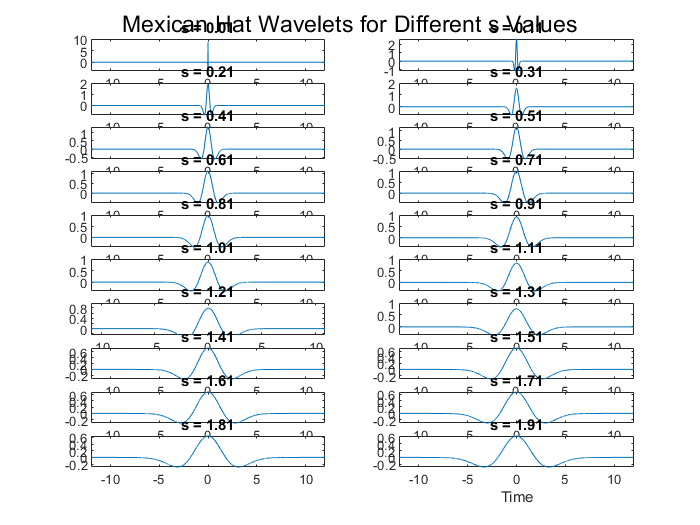

sgtitle('Mexican Hat Wavelets for Different s Values');
xlabel('Time');

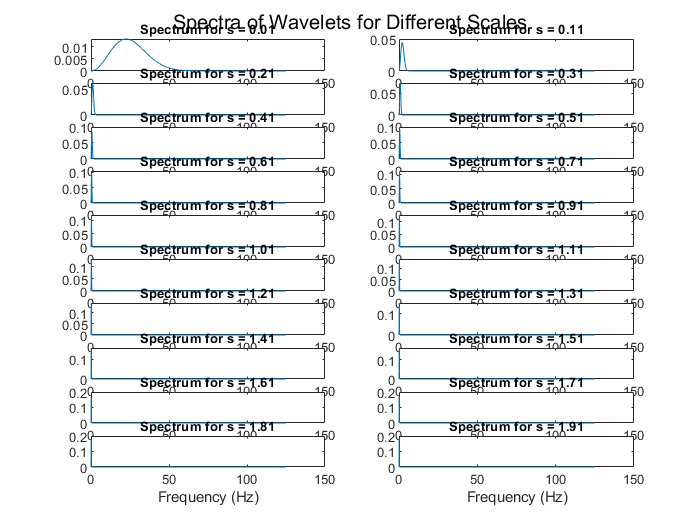


% Figure: Spectra of wavelets

figure;
for i = 1:length(s)
    % Generate the wavelet
    wavelet_s = mexican_hat_wavelet(t, s(i));
    
    % Compute the Fourier Transform for the wavelet spectrum
    Fwavelt = fft(wavelet_s) / length(wavelet_s);
    hz = linspace(0, fs/2, floor(length(wavelet_s) / 2) + 1);
    
    % Plot the wavelet spectrum in a 10x2 grid
    subplot(10, 2, i);
    plot(hz, 2 * abs(Fwavelt(1:length(hz))));
    xlabel('Frequency (Hz)');
    title(['Spectrum for s = ', num2str(s(i))], 'FontSize', 8);
end

sgtitle('Spectra of Wavelets for Different Scales', 'FontSize', 12);

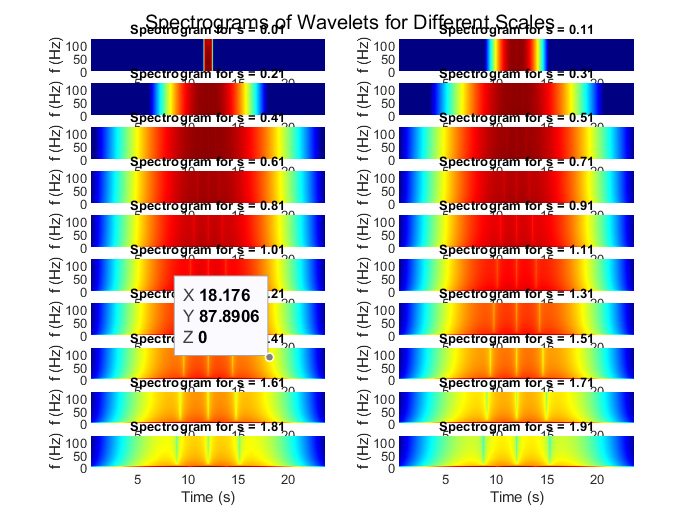


% Figure: Spectrograms of wavelets
figure;
for i = 1:length(s)
    % Generate the wavelet
    wavelet_s = mexican_hat_wavelet(t, s(i));
    
    % Plot the spectrogram in a 10x2 grid
    subplot(10, 2, i);
    [~, F, T, P] = spectrogram(wavelet_s, 128, 120, 128, fs, 'yaxis');
    h = pcolor(T, F, 10 * log10(P)); % Log scale for power
    set(h, 'EdgeColor', 'none'); % Remove grid edges
    colormap jet;
    xlabel('Time (s)');
    ylabel('f (Hz)');
    title(['Spectrogram for s = ', num2str(s(i))], 'FontSize', 8);
end

sgtitle('Spectrograms of Wavelets for Different Scales', 'FontSize', 12);

## 1.3. Continuous Wavelet Decomposition

% Constructing the required signal

N = 3000;

n = (1:3*N);

sin1 = sin(0.5 * pi * n/fs);
sin2 = sin(1.5 * pi * n/fs);

x_n = [sin1(1:3*N/2-1), sin2(3*N/2:end)]

x_n =     0.0063    0.0126    0.0188    0.0251    0.0314    0.0377    0.0440    0.0502    0.0565    0.0628    0.0691    0.0753    0.0816    0.0879    0.0941    0.1004    0.1066    0.1129    0.1191    0.1253    0.1316    0.1378    0.1440    0.1502    0.1564    0.1626    0.1688    0.1750    0.1812    0.1874    0.1935    0.1997    0.2059    0.2120    0.2181    0.2243    0.2304    0.2365    0.2426    0.2487    0.2548    0.2608    0.2669    0.2730    0.2790    0.2850    0.2910    0.2970    0.3030    0.3090


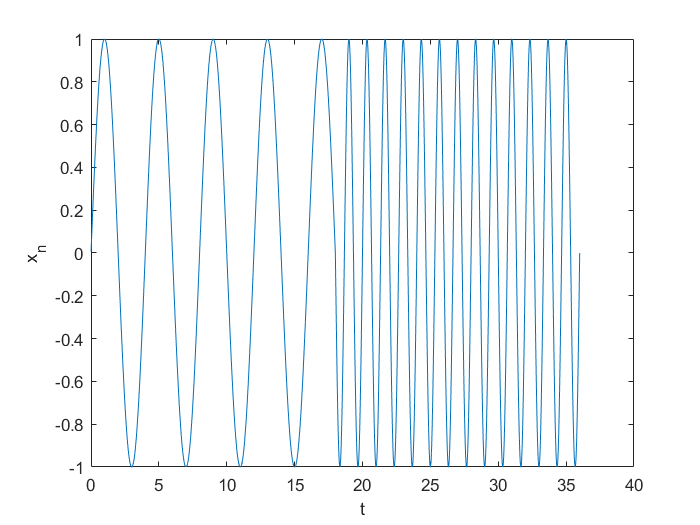


% Visualize 

figure;
plot(n/fs,x_n);
xlabel('t');
ylabel('x_n');

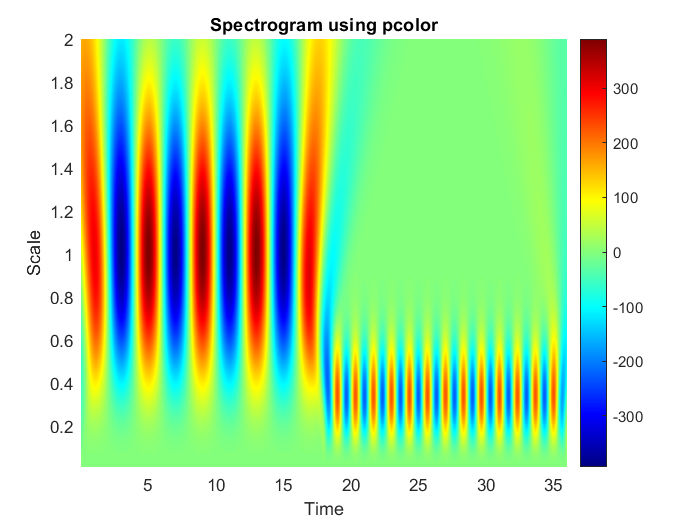

s = 0.01:0.01:2;     % Values of scaling factor
fs = 250;           % Sample frequency

% Stores wavelet coefficients corresponding to different scales

wavelet_coefs = zeros(length(s),length(x_n));


for j = 1:length(s)
    % Scaled wavelet
    wavelet_s = mexican_hat_wavelet(t, s(j));
    
    % Applying scaled wavelet to signal
    X_s = conv(x_n,wavelet_s,'same');
    
    wavelet_coefs(j,:) = X_s;
end

% Visualize

figure;
h = pcolor((1:3*N)/fs, s, wavelet_coefs); 
set(h, 'EdgeColor', 'none');
colormap jet;
colorbar;
xlabel('Time');
ylabel('Scale');
title('Spectrogram using pcolor');